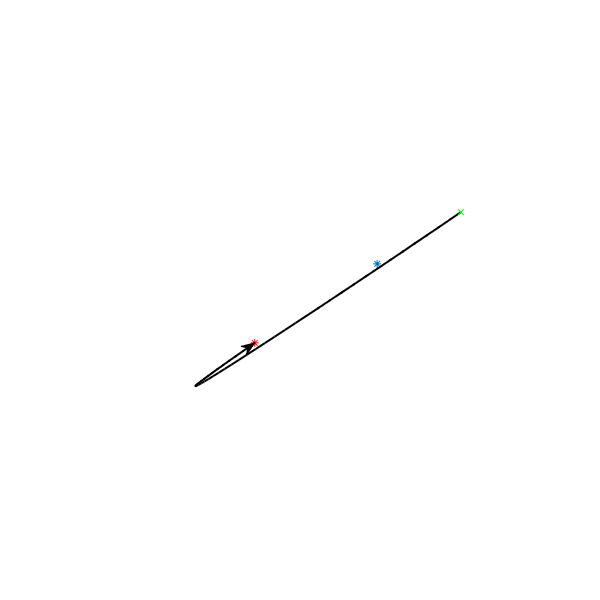

h_fig = figure(1);
clf
set(h_fig,'Visible','on')
set(h_fig, "Position", [1487 408 600 600])
set(h_fig,'color','w');
camproj('perspective')
axis equal off
%axis on

view(80,20)
hold on

% center = [1;2;3]
% tail = center + [1;0;0];
% theta = pi/2;
% k = [0;0;1];

center = rand_vec;
tail = center + rand_vec;
theta = rand*2*pi;
k = cross(rand_vec, tail-center);
k = k/norm(k);

head = center + rot(k, theta)*(tail-center);

plot3(center(1), center(2), center(3), '*')
plot3(tail(1), tail(2), tail(3), 'xg')
plot3(head(1), head(2), head(3), 'r*')

update_list = {
diagrams.angle_arc(tail, k, center, theta);
};

diagrams.runall(update_list)

hold off
set(h_fig,'KeyPressFcn',@(~,~)diagrams.runall(update_list));
set(h_fig, 'renderer', 'painters')

function v = rand_vec()
    v = rand([3 1]);
end